# Analyze 2nd Pull

The weightlifting clean can be broken into 3 pulls: 1) pull from the ground, 2) pull from above the knee to full hip extension, and 3) pulling oneself under the bar to catch it. The arrow in the photo shows Randy's 2nd pull. Pulling the bar higher in the 2nd pull gives the lifter more time to get under the bar and catch it.

I'll look at the height and speed the bar reaches in the 2nd pull. Randy Triunfel (ig thebarbellmasochist) is a competitive weightlifter and my coach.

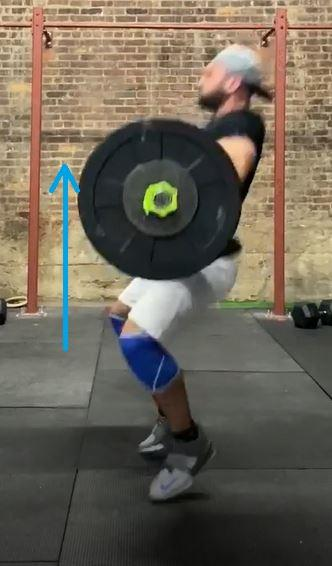

## Get the data

The weights (lbs) are from my notes.

weights = [75 135 165 185 205 225 255 275 295 315 325 335 335];

Next I get the plate locations in the videos using liftVid from BarTrace

for n = 1:13
    fname = "2020_01_05_" + n + "_Trim.mp4";
    vid = liftVid(fname);
    vid.tracePlate("modelC");
    data(n).centers = vid.centers;
    data(n).weight = weights(n);
end

starting
starting
starting
starting
starting
starting
starting
starting
starting
starting
starting
starting
starting


I'll trim the data for lift #9 to cut when Randy walked in front of the bar obscuring it.

%trim data 
data(9).centers = data(9).centers(200:end,:);

Now I'll save this data so I don't need to run from the start again.

save("barpaths.mat","data")

## Plot bar paths: height vs frame/time

data = load("barpaths.mat");
data = data.data;

Let's look at all the bar paths. 

Pixels count from top to bottom, but I like to think of bottom to top, so I subtract the position from the frame height (1280). 

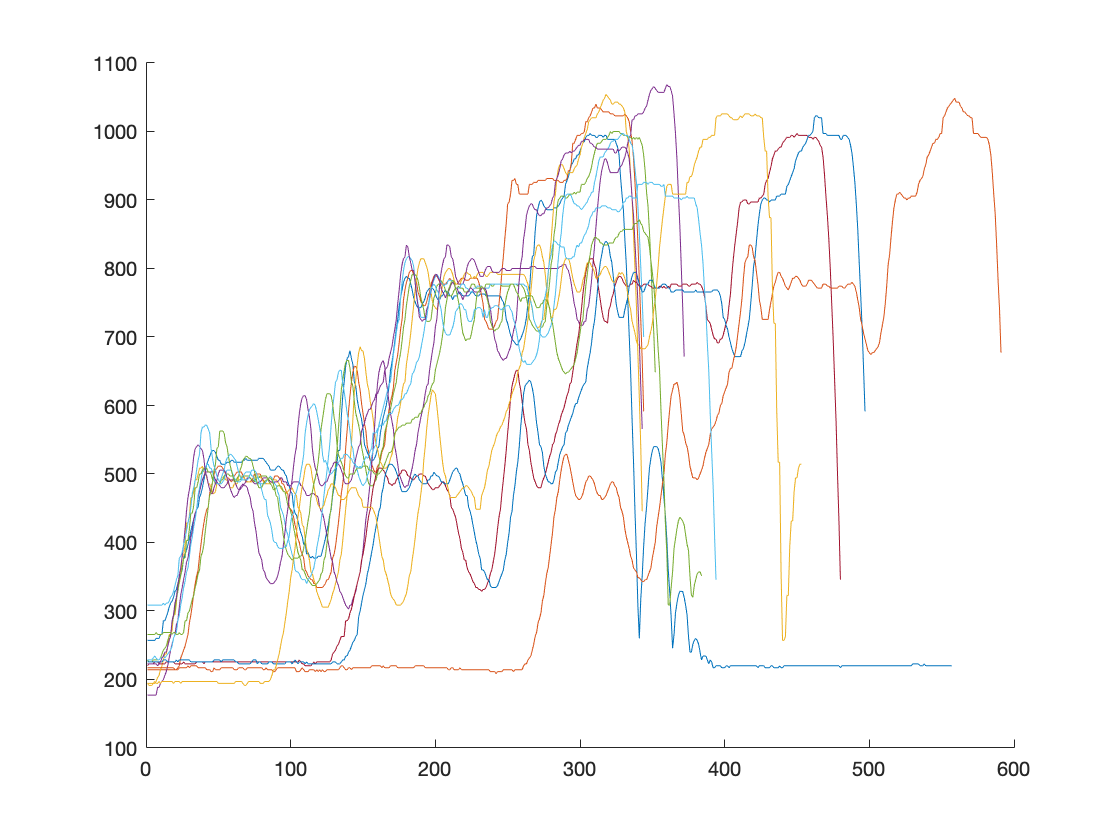

figure; hold on;
for n = 1:13
    plot(1280 - data(n).centers(:,2));
end

The x axes are significantly shifted since I started the video at different times relative to Randy's lift. And the y axis is slightly shifted because both Randy and the camera shifted a little video to video. Let's resolve these shifts. 

The y shift is easy, I'll take the lowest non-zero value as the likely resting position on the floor.

For the x shift, I'll use the verticle peak in the 2nd pull. getOffSet() will get the position of this peak. It uses findpeaks + some of the peak's characteristics (the 2nd pull peak has a unique height, width, and prominance). 

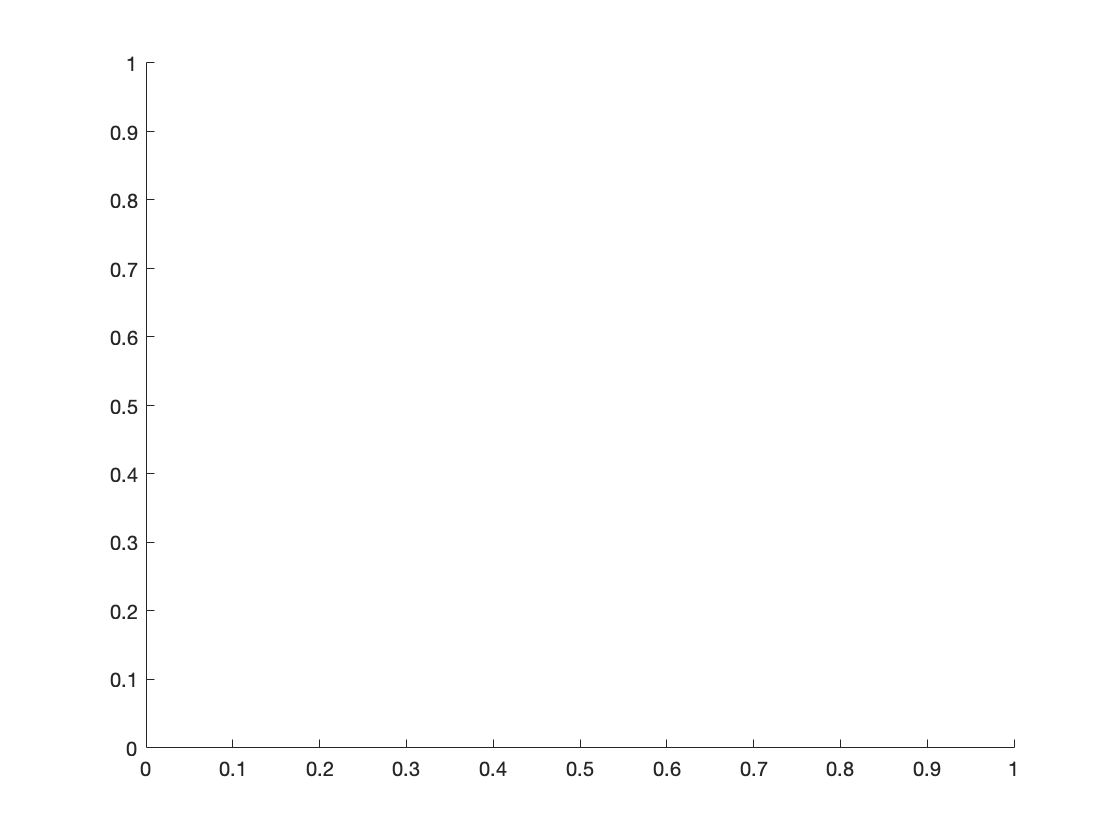

figure; hold on;

for n = 1:13
    y = 1280 - data(n).centers(:,2);       % height measured from bottom
    y = y - min(y(y~=0));                  % shift height relative to ground
    x = 1:length(y);                       % time is just index for now
    [pks, locs, w, p] = findpeaks(y);      % get the peaks
    t = table(pks,locs,w,p,'VariableNames',["pks","locs","w","p"]);
    t(t.w < 5 | t.w > 15,:) = [];          % filter down to the high pull
    t(t.p < 50 | t.p > 200,:) = [];        % filter down to the high pull
    x = x - t.locs(1);                     % shift x by the peak location
    pk(n) = t.pks(1);                      % capture the height of the high pull
    idx = (x>-20) & (x<0);                 % window time down to the 2nd pull
    f = polyfit(x(idx)',y(idx),1);         % fit a line to the 2nd pull
    c(n) = f(1);                           % capture the slope (speed)
    plot(x,y)
end

'findpeaks' requires Signal Processing Toolbox.

## plot results

Olympic weightlifing plates are are 450mm in diameter. The plate appears to be 200 pixels diameter in the video. So 450/200 mm of distance per pixel at a frame speed of 30 frames/sec. pk is the peak height and c is the general slope pixels/frame toward that peak.

figure; hold on;
yyaxis left
plot(weights,450/200*pk/1000,'b*-')
xlabel("Weight (lbs)")
ylabel("Height (m)")
yyaxis right
plot(weights,(450/200)*30*c/1000,'r*-')
ylabel("Speed (m/s)")

## Summary of Results

When the weight gets heavy, it's hard to pull high and fast. Ok. That was pretty obvious. But fun nonetheless to see.